port_name = "COM4";
baud = 115200;
N_MEL = 32;
N_DCT = 8;
nbits_coef = 16;
frac_coef  = 14;
scale_coef = 2^frac_coef;
nbits_out  = 16;

s = serialport(port_name, baud, "Timeout", 10);
flush(s);

start_code = uint8([hex2dec('03') hex2dec('CC') hex2dec('AA') hex2dec('55')]);
stop_code  = uint8([hex2dec('CC') hex2dec('03') hex2dec('55') hex2dec('AA')]);

data_bytes2 = [];

for frame_idx = 1:2
    buf = uint8([]);
    got_start = false;
    while true
        b = read(s,1,"uint8");
        if isempty(b)
            error("Timeout while waiting for frame %d", frame_idx);
        end
        buf(end+1) = b;
        if ~got_start
            if numel(buf) >= 4 && isequal(buf(end-3:end), start_code)
                got_start = true;
                buf = uint8([]);
            end
        else
            if numel(buf) >= 4 && isequal(buf(end-3:end), stop_code)
                payload = buf(1:end-4);
                if numel(payload) < N_DCT*4
                    payload = [payload; zeros(N_DCT*4-numel(payload),1,"uint8")];
                else
                    payload = payload(1:N_DCT*4);
                end
                if frame_idx == 2
                    data_bytes2 = payload;
                end
                break;
            end
        end
    end
end

clear s;

data_bytes = data_bytes2;

dct_words = zeros(N_DCT,1,"uint32");
for k = 1:N_DCT
    b = data_bytes(4*k-3:4*k);
    dct_words(k) = uint32(b(1)) + bitshift(uint32(b(2)),8) + ...
                   bitshift(uint32(b(3)),16) + bitshift(uint32(b(4)),24);
end

dct_u16  = uint16(bitand(dct_words, uint32(65535)));
dct_fpga = typecast(dct_u16,"int16");

M = N_MEL;
N = 13;
C = zeros(N,M);
for n = 0:N-1
    for m = 0:M-1
        C(n+1,m+1) = cos(pi*n*(m+0.5)/M);
    end
end

Cq = round(C * scale_coef);
max_val = 2^(nbits_coef-1)-1;
min_val = -2^(nbits_coef-1);
Cq(Cq > max_val) = max_val;
Cq(Cq < min_val) = min_val;

if exist("mel_fpga","var") ~= 1
    error("mel_fpga (32 MEL energies) must be in workspace");
end

mel_vec = double(mel_fpga(:));

acc = double(Cq) * mel_vec;
dct_ref = round(acc / 2^frac_coef);
max_out = 2^(nbits_out-1)-1;
min_out = -2^(nbits_out-1);
dct_ref(dct_ref > max_out) = max_out;
dct_ref(dct_ref < min_out) = min_out;
dct_ref = int16(dct_ref(1:N_DCT));

fprintf("FPGA DCT coefficients:\n");

FPGA DCT coefficients:


disp(dct_fpga(:).');

   -30467    30155    16816    -1153   -18659   -30776    31383   -27952




fprintf("MATLAB fixed-point DCT coefficients:\n");

MATLAB fixed-point DCT coefficients:


disp(dct_ref(:).');

    32767    30266    16876    -1161   -18732   -30896   -32768   -28061




diff = double(dct_fpga) - double(dct_ref);
fprintf("Difference (FPGA - MATLAB):\n");

Difference (FPGA - MATLAB):


disp(diff(:).');

      -63234        -111         -60           8          73         120       64151         109



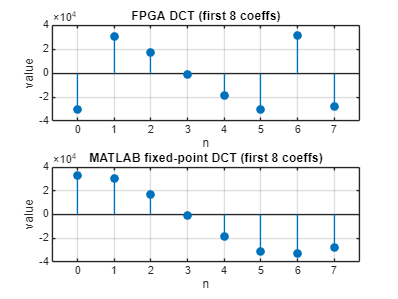


figure;
subplot(2,1,1);
stem(0:N_DCT-1,double(dct_fpga),'filled');
title('FPGA DCT (first 8 coeffs)');
xlabel('n');
ylabel('value');
grid on;

subplot(2,1,2);
stem(0:N_DCT-1,double(dct_ref),'filled');
title('MATLAB fixed-point DCT (first 8 coeffs)');
xlabel('n');
ylabel('value');
grid on;